## Compare Storm Events with Weather Data

## Merge event data with weather data

weather = thingSpeakRead(12397,...
   "DateRange",[datetime("Mar 11, 2017"),datetime("Mar 15, 2017")],...
   "OutputFormat","timetable");  

Update the variable names.

weather.Properties.VariableNames = ["WindDir","WindSpeed",...
    "Humidity","TempF","Rain","Pressure","Power","Intensity"];

weather

weather = 5577×8 timetable
         Timestamps         WindDir    WindSpeed    Humidity    TempF    Rain    Pressure    Power    Intensity
    ____________________    _______    _________    ________    _____    ____    ________    _____    _________
    11-Mar-2017 00:00:29       39         4.1          53       27.7      0        29.6        4         38    
    11-Mar-2017 00:01:30       38         4.3          53       27.7      0        29.6        4         46    
    11-Mar-2017 00:02:30       21         6.3          53       27.7      0        29.6        4         44    
    11-Mar-2017 00:03:31      357      

Visualize the weather data.

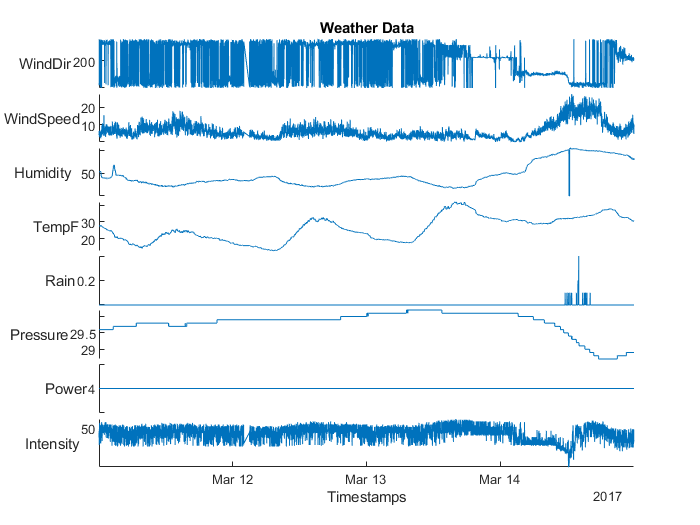

stackedplot(weather);
title("Weather Data")

## Work with outliers

Determine locations of the outliers and visualize.

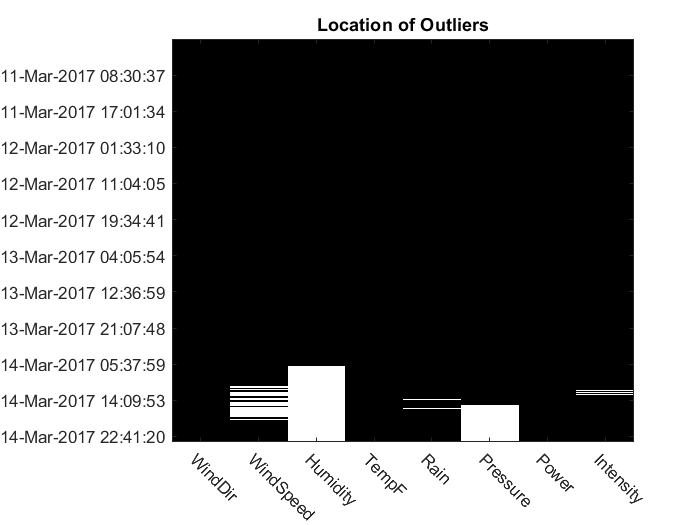

idx = isoutlier(weather,"median");   
visualizeTableMask(weather,idx); 

We could remove, ignore, or fill the outliers with various methods in `rmoutliers` and `filloutliers`.

weather = filloutliers(weather,"center","median",...
        "DataVariables","Intensity");   

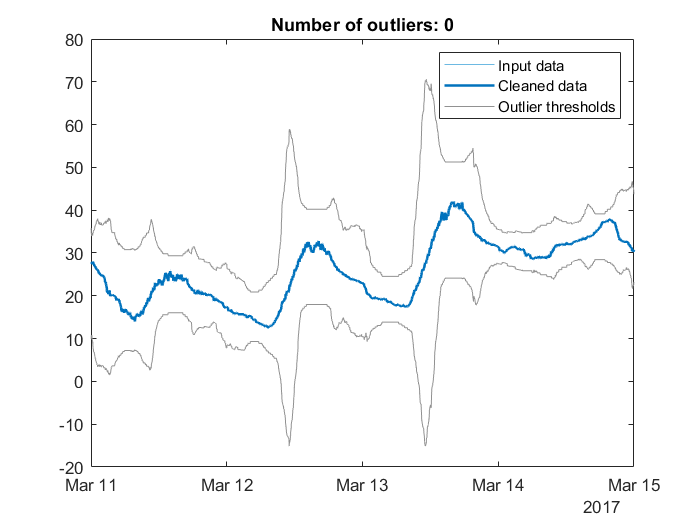

% Fill outliers
[cleanedData,outlierIndices,thresholdLow,thresholdHigh] = ...
    filloutliers(weather.TempF,'spline','movmedian',days(0.44),...
    'SamplePoints',weather.Timestamps);

% Display results
clf
plot(weather.Timestamps,weather.TempF,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on
plot(weather.Timestamps,cleanedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(weather.Timestamps(outlierIndices),weather.TempF(outlierIndices),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Plot filled outliers
plot(weather.Timestamps(outlierIndices),cleanedData(outlierIndices),'.',...
    'MarkerSize',12,'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([weather.Timestamps(:); missing; weather.Timestamps(:)],...
    [thresholdHigh(:); missing; thresholdLow(:)],'Color',[145 145 145]/255,...
    'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices thresholdLow thresholdHigh

## Resample the data

Resample the data so the times and data are uniformly spaced on the minute.

wdata = retime(weather(:,vartype("numeric")),...
    "minutely","linear");

% tempHumidityPlot(wdata)

## Smooth noisy data     

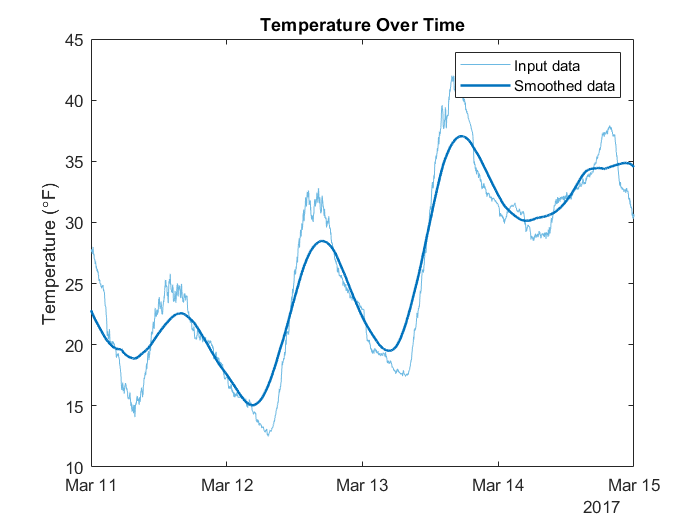

% Smooth input data
smdata = smoothdata(wdata.TempF,'movmean','SmoothingFactor',0.25,...
    'SamplePoints',wdata.Timestamps);

% Visualize results
clf
plot(wdata.Timestamps,wdata.TempF,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on
plot(wdata.Timestamps,smdata,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend
ylabel("Temperature (\circF)")
title("Temperature Over Time")    

## Changepoint detection

Detect local maxima and minima in the smoothed data to determine drastic temperature changes. You can use the following functions or the Live Editor Task to perform these steps.

- `islocalmin`

- `islocalmax`

- `ischange`

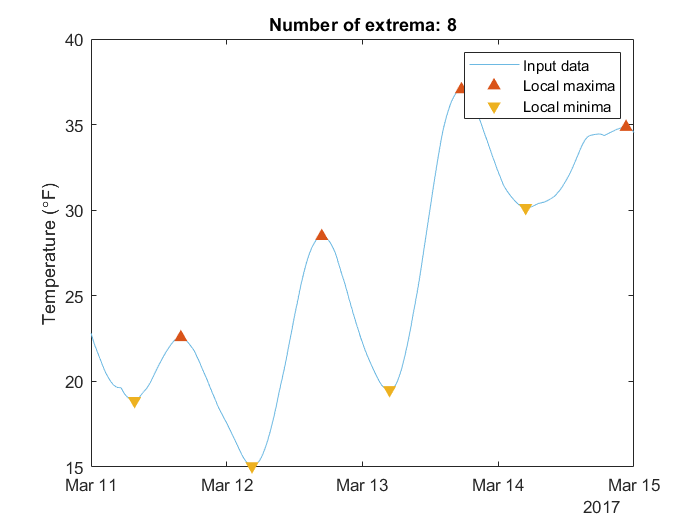

hiTemps = 4×8 timetable
         Timestamps         WindDir    WindSpeed    Humidity    TempF     Rain    Pressure    Power    Intensity
    ____________________    _______    _________    ________    ______    ____    ________    _____    _________
    11-Mar-2017 15:53:00    338.03       4.0968        27       23.913     0        29.8        4       44.871  
    12-Mar-2017 16:48:00      20.4          3.3        23        31.74     0        29.9        4         50.4  
    13-Mar-2017 17:30:00    259.11      0.28226        18       41.435     0        30.1        4           46  
    14-Mar-2017 22:36:00    232.02   

lowTemps = 4×8 timetable
         Timestamps         WindDir    WindSpeed    Humidity    TempF     Rain    Pressure    Power    Intensity
    ____________________    _______    _________    ________    ______    ____    ________    _____    _________
    11-Mar-2017 07:42:00    53.475      7.8098       29.426     15.043     0        29.8        4       50.738  
    12-Mar-2017 04:28:00    153.92      6.1738           39     14.685     0        29.9        4       40.443  
    13-Mar-2017 04:47:00       296      2.2306           41       18.6     0        30.1        4       46.177  
    14-Mar-2017 04:51:00    94.306  

if DetectChangePoints
    

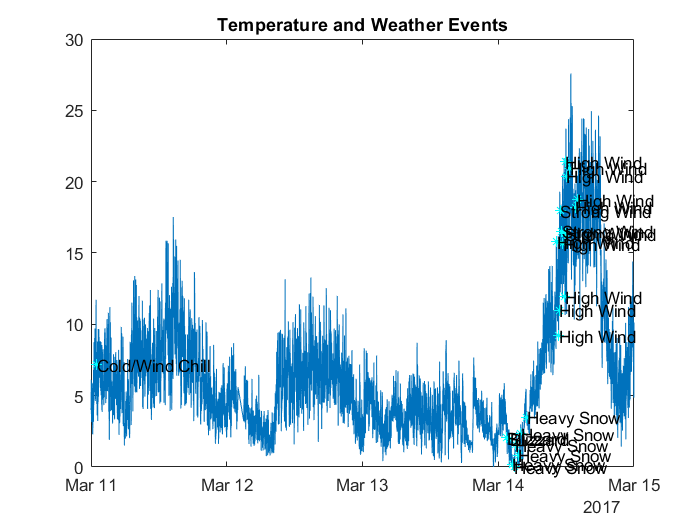

% Find local maxima and minima
maxIndices = islocalmax(smdata,'MinProminence',0.1,'ProminenceWindow',days(1),...
    'MaxNumExtrema',10,'SamplePoints',wdata.Timestamps);
minIndices = islocalmin(smdata,'MinProminence',0.1,'ProminenceWindow',days(1),...
    'MaxNumExtrema',10,'SamplePoints',wdata.Timestamps);

% Visualize results
clf
plot(wdata.Timestamps,smdata,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on

% Plot local maxima
plot(wdata.Timestamps(maxIndices),smdata(maxIndices),'^',...
    'Color',[217 83 25]/255,'MarkerFaceColor',[217 83 25]/255,...
    'DisplayName','Local maxima')

% Plot local minima
plot(wdata.Timestamps(minIndices),smdata(minIndices),'v',...
    'Color',[237 177 32]/255,'MarkerFaceColor',[237 177 32]/255,...
    'DisplayName','Local minima')
title(['Number of extrema: ' num2str(nnz(maxIndices)+nnz(minIndices))])
hold off
legend

    ylabel("Temperature (\circF)")
    % Determine high and low temperatures
    hiTemps = wdata(maxIndices,:)
    lowTemps = wdata(minIndices,:)
end

## Normalize and rescale data

if NormalizeAndRescale
    weatherNorm = normalize(weather(:,vartype("numeric")));
    weatherNorm = rescale(weatherNorm.Variables,0,1);
    figure
    plot(weather.Timestamps,weatherNorm(:,3:4))
    title("Normalized and Rescaled Data")
    legend("Temp","Humidity")
end

## Synchronize data

Select data from the location of the weather sensors.

eventsMA = data(data.state == "MASSACHUSETTS","event_type");

Synchronize the two timetables using the times in `wdata` as the common time. (See also the Synchronize Live Editor Task to explore methods for  managing the data and times)

weatherMA = synchronize(wdata,eventsMA,"first");
eventsMA = weatherMA(~ismissing(weatherMA.event_type),:);

figure
plot(wdata.Timestamps,wdata.WindSpeed)
hold on
plot(eventsMA.Timestamps,eventsMA.WindSpeed,"c*")
text(eventsMA.Timestamps,eventsMA.WindSpeed,string(eventsMA.event_type))
hold off
title("Temperature and Weather Events")

## Grouped calculations

Determine the average temperature each day and any events which occured. There are a number of options for methods in the `retime` and `synchronize` functions, appropriate for the various data types.

weatherTH = rmmissing(weather,"DataVariables",...
    ["TempF","Humidity"]);
w1 = retime(weatherTH(:,["TempF","Humidity"]),...
    "daily","mean");
w2 = retime(eventsMA(:,"event_type"),...
    "daily","nearest");
dailyWeather = synchronize(w1,w2);

Calculate the average temperature by the hour of day.

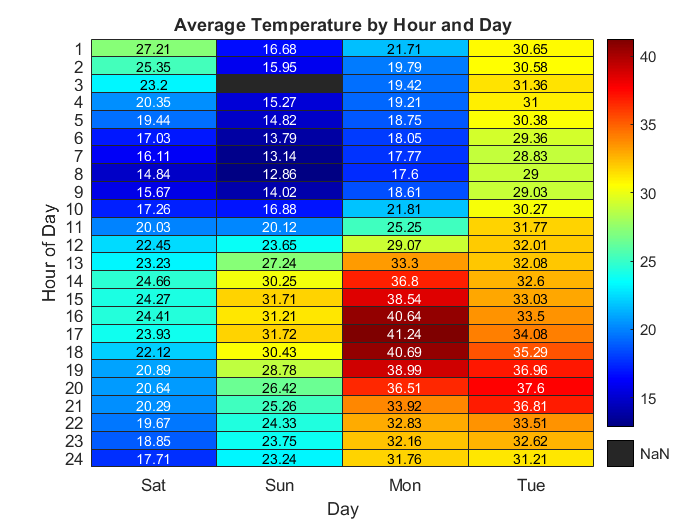

mnByDay = groupsummary(weather,"Timestamps","dayname",...
    "mean",["TempF","Humidity"],"IncludeMissingGroups",true,"IncludeEmptyGroups",true);

mnByHr = groupsummary(weather,"Timestamps","hourofday",...
    "mean",["TempF","Humidity"],"IncludeMissingGroups",true,"IncludeEmptyGroups",true);

Rearrange the table and visualize as a heatmap.

weather.hh = hour(weather.Timestamps);
weather.dd = day(weather.Timestamps,"shortname");
dayHr = groupsummary(weather,["dd","hh"],"mean","TempF","IncludeMissingGroups",true,...
    "IncludeEmptyGroups",true);
dayHr = unstack(dayHr(:,["hh","dd","mean_TempF"]),"mean_TempF","dd");
idx = all(ismissing(dayHr));
dayHr(:,idx) = [];
dayHr.hh = hours(dayHr.hh);
dayHr = table2timetable(dayHr);
daynames = ["Sat","Sun","Mon","Tue"]; 
dayHr = dayHr(:,daynames);

figure 
h = heatmap(daynames,string(1:24),dayHr.Variables);
h.Colormap = jet;
xlabel("Day")
ylabel("Hour of Day")
title("Average Temperature by Hour and Day")

**Helper functions**

function visualizeTableMask(weatherData,idx)
figure
imagesc(idx)
xticklabels(weatherData.Properties.VariableNames)
xtickangle(-45)
ys = yticks;
yticklabels(cellstr(weatherData.Timestamps(ys)))
title("Location of Outliers")
colormap gray
end

function tempHumidityPlot(wdata)
figure
yyaxis left
plot(wdata.Timestamps,wdata.TempF)
ylabel("Temperature (\circF)")
yyaxis right
plot(wdata.Timestamps,wdata.Humidity)
ylabel("% Humidity")
title("Temperature and Humidity Over Time")
end